# RUN 4th

% Average hourly price of 1 year
% The frequency of operation in each time slot

% RegionID = 'QLD1';
% timespan = datetime(2011,1,1):calmonths(1):datetime(2022,12,1);
% % PlantName are Wivenhoe, Shoalhaven, Tumut3. Case insensitive, e.g. ShOalHaVen is fine.
% PHSdata = funcPHSdata(timespan, RegionID,'WIVENHOE');

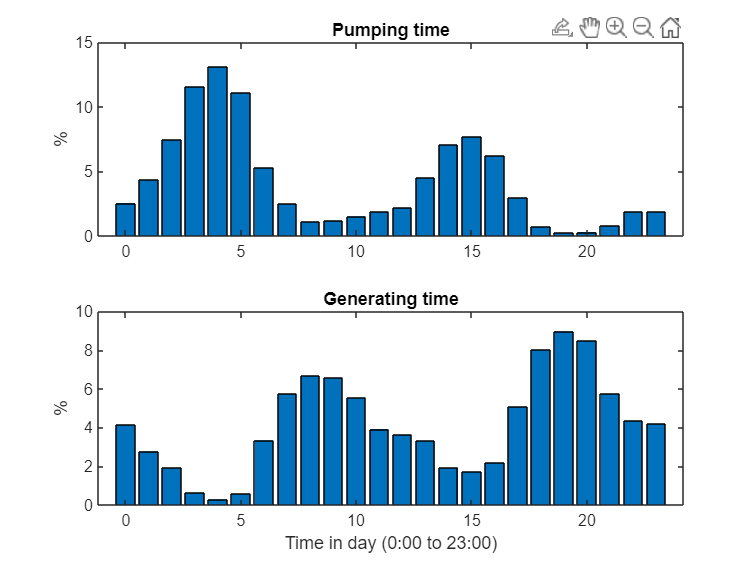

tic
% select a year for the analysis
slyear = 2022;
% index1 points out the segment belongs to slyear
idx1 = year(PHSdata.SETTLEMENTDATE)==slyear;
meanPrice=[];countPump=[];countGen=[];
for ii = 0:23
    % index2 points out the segment
    idx2 = hour(PHSdata.SETTLEMENTDATE)==ii;
    idx = idx1 & idx2;
    meanPrice(ii+1) = mean(PHSdata.RRP(idx));
%     medPrice(ii+1) = median(PHSdata.RRP(idx));

    idx3 = PHSdata.PHSpump>0;
    idx = idx1 & idx2 & idx3;
    countPump(ii+1) = sum(idx);

    idx3 = PHSdata.PHSgen>0;
    idx = idx1 & idx2 & idx3;
    countGen(ii+1) = sum(idx);
end
kPump = countPump/sum(countPump);
kGen = countGen/sum(countGen);

clf
% subplot(3,1,1);
%     bar(0:23,meanPrice);
%     ylim([0 600])
subplot(2,1,1);
    bar(0:23,kPump*100);title('Pumping time');ylabel('%');
subplot(2,1,2);
    bar(0:23,kGen*100);title('Generating time');ylabel('%');xlabel('Time in day (0:00 to 23:00)')


toc

Elapsed time is 0.241040 seconds.
